# Computational Methods in Physics (PHY4605) - **Numerical Root-Finding and Calculus**

## Overview

A major scientific use of computers is in finding numerical solutions to mathematical problems which have no analytical solutions. In this chapter we look at some areas where numerical methods have been highly developed, e.g., solving non-linear equation, evaluating integrals and computing differentiation. For each method discussed, MATLAB provides built-in functions to achieve the same computation. You may think there is no point in developing our own functions to handle these numerical procedures when MATLAB has its own. However, it is important to study the mathematical background of the methods first before using the functions so you know how they work rather than treating them simply as ‘black boxes’.

## Numerical Root-Finding

The usual way of expressing the problem is to say that we want to solve the equation $f\left(x\right)=0$, i.e., we want to find its root (or roots). This process is also described as finding the zeros of $f\left(x\right)$. There is no general method for finding roots analytically for an arbitrary $f\left(x\right)$.

### Newton's Method

Newton’s method is perhaps the easiest numerical method to implement for solving equations. It is an iterative method, meaning that it repeatedly attempts to improve an estimate of the root. If $x_k$ is an approximation to the root, we can relate it to the next approximation $x_{k+1}$ using the right-angle triangle:

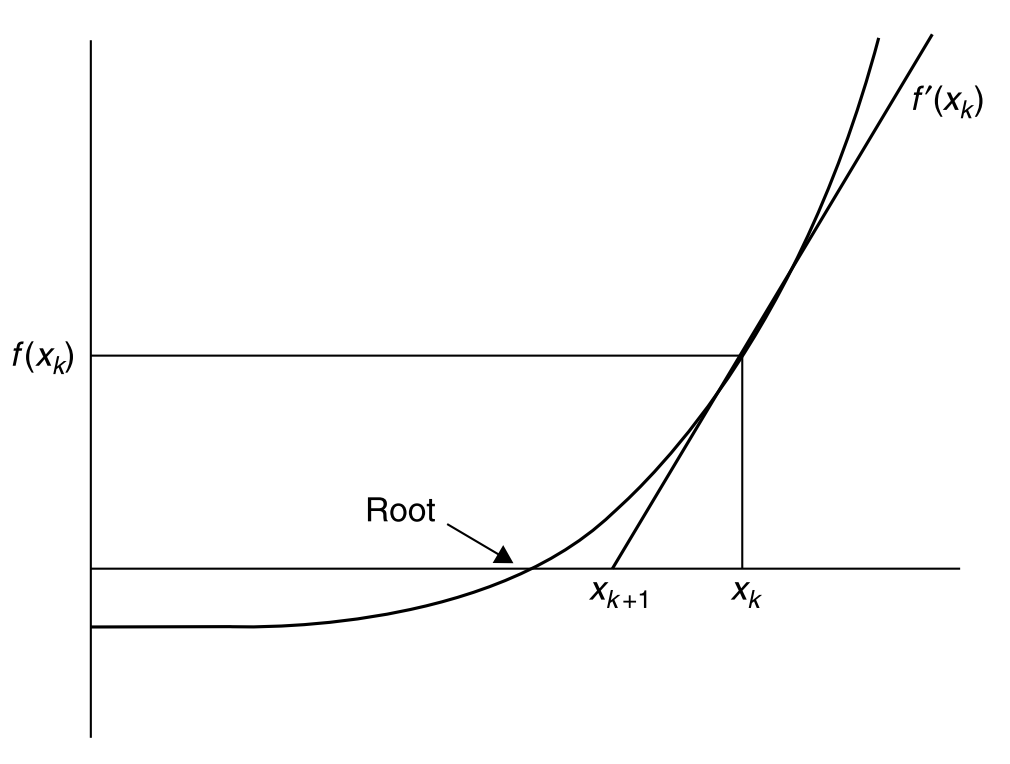

$f^{\prime } \left(x_k \right)=\frac{f\left(x_k \right)-0}{x_k -x_{k+1} }$, where $f^{\prime } \left(x\right)$ is $\textrm{df}/\textrm{dx}$. Solving for $x_{k+1}$ gives: $x_{k+1} =x_k -\frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$.

A structure plan to implement Newton’s method is:

- Input starting value $x_0$ and required relative error $e$

- While relative error $\left|\left(x_k -x_{k-1} \right)/x_k \right|\ge e$ repeat up to $k=20$, say $x_{k+1} =x_k -f\left(x_k \right)/f^{\prime } \left(x_k \right)$, print $x_{k+1}$ and $f\left(x_{k+1} \right)$ 

- Stop

The function `newtonSolver` has been enhanced to enable it to accept any function $f\left(x\right)$ and its first drivative $f^{\prime } \left(x\right)$ as input arguments by defining them as function handles.

As an exercise, use Newton’s method to find a root of $x^3 -2x-5=0$. This is the example used when the algorithm was first presented to the French Academy.

format long
f = @(x) x^3 - 2*x - 5;
df = @(x) 3*x^2 - 2;
x0 = 5;
newtonSolver(f, df, x0)

Also try finding a non-zero root of $2x=\tan \left(x\right)$, using Newton’s method:

f = @(x) 2*x - tan(x);
df = @(x) 2 - (tan(x)^2 + 1);
x0 = 5;
newtonSolver(f, df, x0)

You might have some trouble with this one. If you do, you will have discovered the one serious problem with Newton’s method: it converges to a root only if the starting guess is ‘close enough’. Since ‘close enough’ depends on the nature of $f\left(x\right)$ and on the root, one can obviously get into difficulties here. If Newton’s method fails to find a root, the Bisection method that is discussed next, can be used.

### Bisection Method

Through this method, we attempt to find by inspection, or trial-and-error, two values of $x$, call them $x_L$ and $x_R$, such that $f\left(x_L \right)$ and $f\left(x_R \right)$ have different signs, i.e., $f\left(x_L \right)f\left(x_R \right)<0$. If we can find two such values, the root must lie somewhere in the interval between them, since $f\left(x\right)$ changes sign on this interval. 

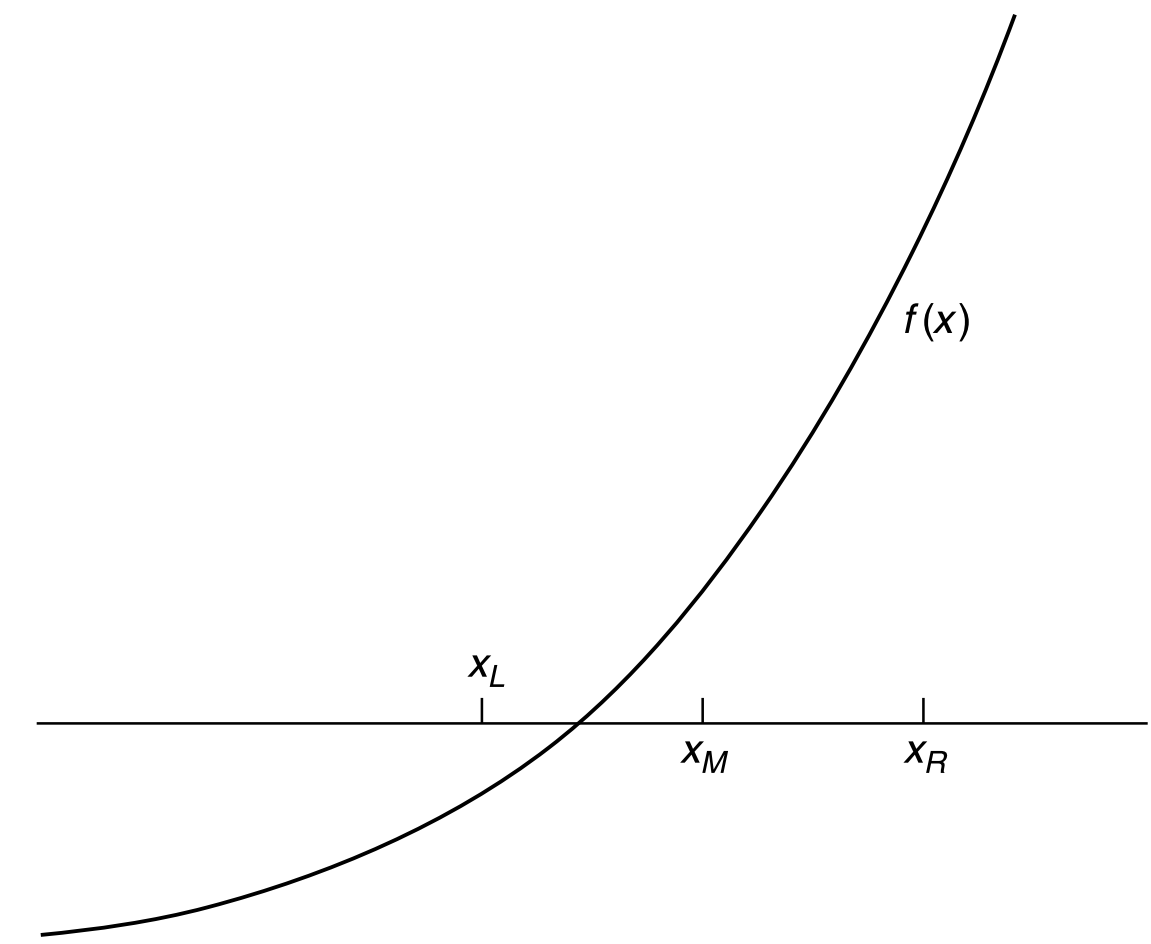

Consider again the problem of solving the equation $f\left(x\right)=0$, where $f\left(x\right)=x^3 +x-3$. We start with $x_L =1$ and $x_R =2$ will do, since $f\left(1\right)=-1$ and $f\left(2\right)=7$. In the Bisection method, we estimate the root by $x_M$, which is the midpoint of the interval $\left\lbrack x_L ,\;x_R \right\rbrack$, i.e., $x_M =\left(x_: +x_R \right)/2\ldotp$ Then, check which of the following case is true:

- If $f\left(x_M \right)=0$, then we have found the root.

- If $f\left(x_M \right)$ has the same sign as $f\left(x_R \right)$ that means the root clearly lies between $x_M$ and $x_L$, then we replace $x_{R\;}$ with $x_M$ and keep $x_L$. This case is exemplified in the figure above.

- If $f\left(x_M \right)$ has the same sign as $f\left(x_L \right)$ that means the root clearly lies between $x_M$ and $x_R$, then we replace $x_{L\;}$ with $x_M$ and keep $x_R$.

Having redefined $x_L$ or $x_R$, we bisect the new interval again (calculating the new $x_M$) and repeat the process until the distance between $x_L$ and $x_R$ is as small as we require:

f = @(x) x^3 + x - 3;
[xL, xR] = deal(1, 2);
bisectionSolver(f, xL, xR)

The main advantage of the Bisection method is that it is guaranteed to find a root if you can find two starting values for $x_L$ and $x_R$ between which the function changes sign.  However, compared to Newton’s method, the Bisection method is inefficient as successive bisections do not necessarily move closer to the root. In fact, it is interesting to compare the two methods on the same functions:

f = @(x) x^3 - 2*x - 5;
[xL, xR] = deal(0, 5);
bisectionSolver(f, xL, xR)

f = @(x) 2*x - tan(x);
[xL, xR] = deal(0, 3);
bisectionSolver(f, xL, xR)

### Built-In Functions

The function `fzero(@f, a)` finds the zero nearest to the value `a` of a function represented by the function handle `f`. The algorithm, created by T. Dekker, uses a combination of bisection, secant, and inverse quadratic interpolation methods.

Use it to find a zero of $f\left(x\right)=x^3 +x-3$

f = @(x) x^3 + x - 3;
fzero(f, 5)

`fzero` doesn’t appear to be able to find complex roots. Attempting to find the roots for $f\left(x\right)=x^2 -6x+12$:

f = @(x) x^2 - 6*x + 12;
fzero(f, 5)

yields an error. This is because the function has complex roots.

To obtain complex roots, use the function `roots(p)`, that returns the roots of the polynomial represented by `p` as a column vector. To obtain the roots for the previous function, the following function call is made:

roots([1, -6, 12])

## Numerical Integration

Although most mathematical functions can be differentiated analytically, the same cannot be said for integration. There are no general rules for integrating, as there are for differentiating. For example, the indefinite integral of a function as simple as $e^{-x^2 }$ cannot be found analytically. We therefore need numerical methods for evaluating integrals. This is actually quite easy, and depends on the fact that the definite integral of a function $f\left(x\right)$ between the limits $x=a$ and $x=b$ is equal to the area under $f\left(x\right)$ bounded by the x-axis and the two vertical lines  $x=a$ and $x=b$. So all numerical methods for integrating simply involve ways of estimating the area under $f\left(x\right)$.

### Trapezoidal Rule

The area under $f\left(x\right)$ is divided into vertical panels each of width $h$, called the step-length. If there are $n$ such panels, then $\textrm{nh}=b-a$, i.e., $n=\left(b-a\right)/h$. If we join the points where successive panels cut $f\left(x\right)$, we can estimate the area under $f\left(x\right)$ as the sum of the area of the resulting trapezia. If we call this approximation to the integral $S$, then:


$$S=\frac{h}{2}\left\lbrack f\left(a\right)+f\left(b\right)+2\sum_{i=1}^{n-1} f\left(x_i \right)\right\rbrack$$


where $x_i =a+\textrm{ih}$.

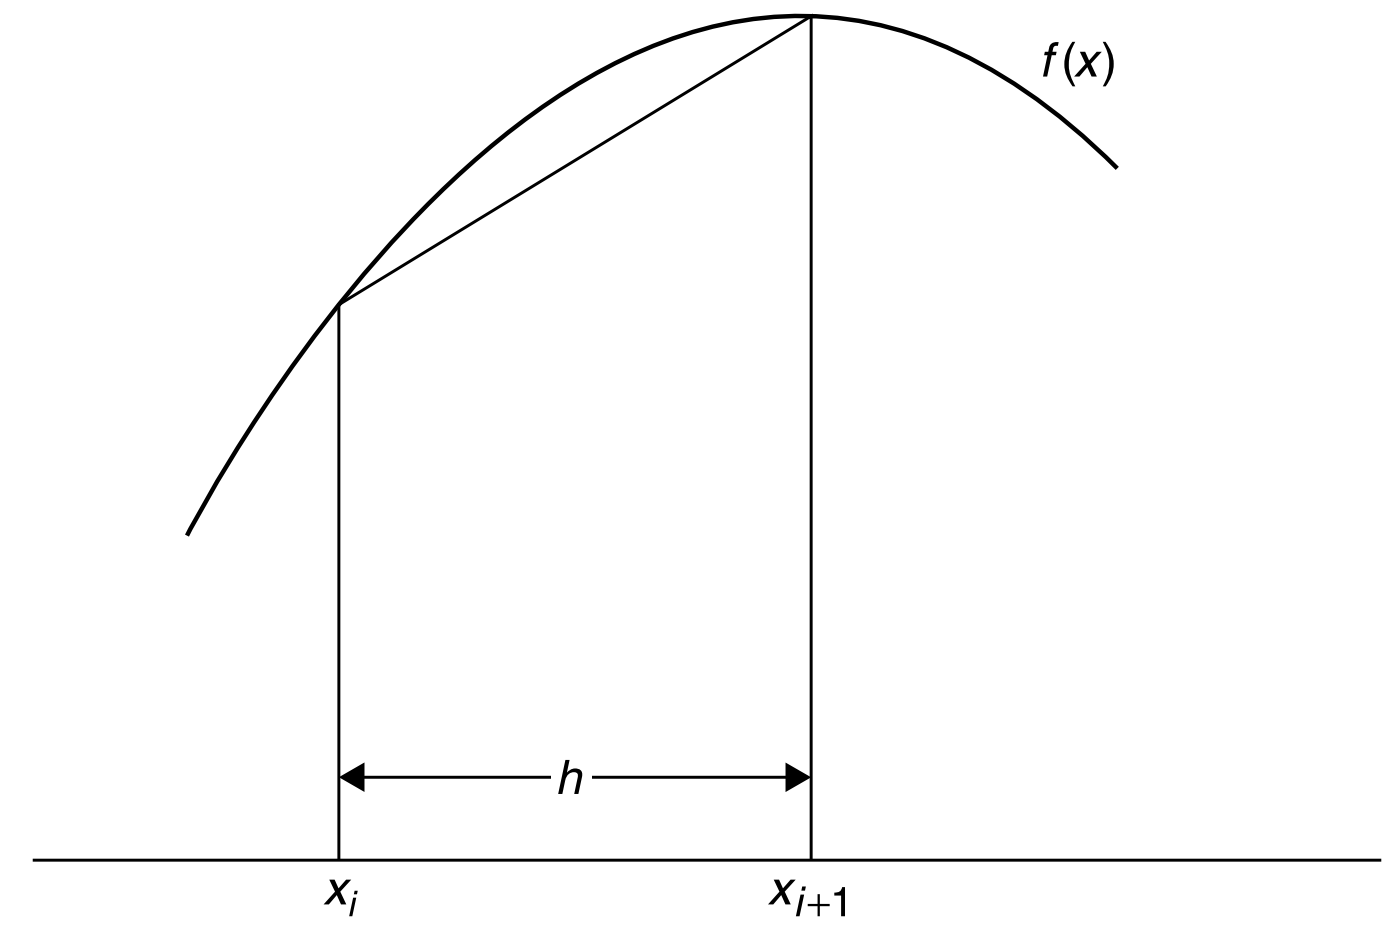

format long
f = @(x) exp(-x.^2);
[a, b] = deal(0, 4);
h = 0.1;
n = (b - a) / h;
x = a + (1 : n - 1) * h;
y = sum(f(x));
TrapezoidInt = h / 2 * (f(a) + f(b) + 2*y)

### Simpson's Rule

Simpson’s rule is a method of numerical integration which is considerably more accurate than the Trapezoidal rule, and should always be used before you try anything more sophisticated. It also divides the area under the function to be integrated, $f\left(x\right)$, into vertical strips, but instead of joining the points $f\left(x_i \right)$ with straight lines, every set of three such successive points is fitted with a parabola. Using the same notation as above, Simpson’s rule estimates the integral as:


$$S=\frac{h}{3}\left\lbrack f\left(a\right)+f\left(b\right)+2\sum_{i=1}^{n-1} f\left(x_{2i} \right)+4\sum_{i=1}^n f\left(x_{2i-1} \right)\right\rbrack$$


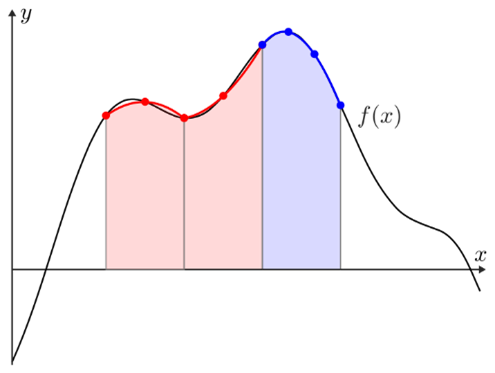

format long
f = @(x) exp(-x.^2);
[a, b] = deal(0, 4);
h = 0.1;
n = (b - a) / h;
xEven = a + (2 : 2 : n - 1) * h;
yEven = sum(f(xEven));
xOdd = a + (1 : 2 : n) * h;
yOdd = sum(f(xOdd));
SimpsonInt = h / 3 * (f(a) + f(b) + 2*yEven + 4*yOdd)

### Built-In Function

MATLAB has a function `integral` to carry out numerical integration:

format long
f = @(x) exp(-x.^2);
[a, b] = deal(0, 4);
Int = integral(f, a, b)

### Physics Pinpoint 🔎: Black Body Radiator

The luminous efficiency (ratio of the energy in the visible spectrum to the total energy) of a black body radiator may be expressed as a percentage by the formula:


$$E=64\ldotp 77T^{-4} \int_{4\times {10}^{-5} }^{7\times {10}^{-5} } x^{-5} {\left(e^{1\ldotp 432/\textrm{Tx}} -1\right)}^{-1} \textrm{dx}$$


where $T$ is the absolute temperature in degrees Kelvin, $x$ is the wavelength in cm, and the range of integration is over the visible spectrum. The `intSimpson(fn, a, b, n) `function implements Simpson’s rule. By taking $T=3500\;\mathrm{K}$, the function is used to compute $E$, with varying values of $n$ to compare the results.

n = 5;
T = 3500;
f = @(x) x.^-5 .* (exp(1.432./(T*x)) - 1).^-1;
[Int, h] = intSimpson(f, 4e-5, 7e-5, n)
E = 64.77 * T^-4 * Int

## Numerical Differentiation

The Newton quotient for a function $f\left(x\right)$ is given by: $\frac{f\left(x+h\right)-f\left(x\right)}{h}$. As $h$ tends to zero, this quotient approaches the first derivative, $\textrm{df}/\textrm{dx}$. The Newton quotient may therefore be used to estimate a derivative numerically. 

It is a useful exercise to do this with a few functions for which you know the derivatives. This way you can see how small you can make $h$ before rounding errors cause problems. As an example, the following script uses the Newton quotient to estimate $f\prime \left(x\right)$ for $f\left(x\right)=x^2$ at $x=2$ for smaller and smaller values of $h$, which we know the exact answer is 4.

f = @(x) x.^2;
x = 2;
h = 10.^(0:-1:-19);
disp('            h                  f''(x)');
for i = 1 : numel(h)
    Quotient(i) = (f(x + h(i)) - f(x)) / h(i);
    fprintf('%.20f %.20f\n', h(i), Quotient(i));
end
semilogx(h, Quotient, '.-');
yline(4, 'r--', 'True value');
xlabel('h');
ylabel('f''(x)')

### Built-In Function

If x is a row or column vector` [x(1), x(2), x(3),... x(n)]` then the MATLAB function `diff(x)` returns a vector of differences between adjacent elements: ` [x(2)-x(1), x(3)-x(2),... x(n)-x(n-1)]`. The output vector is one element shorter than the input vector. In certain problems, `diff` is helpful in finding approximate derivatives, e.g., if `x` contains displacements of an object every `h` seconds, `diff(x)/h` will be its speed.

**Local Functions**

function newtonSolver(f, df, x)
% Solving a polynomial equation to determine the roots through the Newton's method
Iteration = 0;
TargetError = 1e-8; 
MaxIterations = 20;
Error = 1;
disp('      x       f(x)');
fx = inf;
while fx > TargetError && (Iteration < MaxIterations)
    xOld = x;
    x = x - f(x) / df(x);
    Iteration = Iteration + 1;
    disp([x f(x)]);
    fx = abs(f(x));
end
if fx <= TargetError
    fprintf('Root found after %d iterations at %.12f.\n', Iteration, x);
else
    disp('Root not found.');
end
end

function bisectionSolver(f, xL, xR)
% Solving a polynomial equation to determine the roots through the Bisection method
fL = f(xL); 
fR = f(xR);
MaxIterations = 150;
TargetError = 1e-8;
if sign(fL) == sign(fR)
    error('f(xL) and f(xR) have the same sign.')
end
disp('      x       f(x)');
Iteration = 1;
while Iteration < MaxIterations
    xM = (xL + xR) / 2;
    fM = f(xM); 
    if abs(fM) < TargetError 
        fprintf('Root found after %d iterations at %.12f.\n', Iteration, xM);
        return;
    end
    disp([xM fM]);
    if sign(fL) == sign(fM) 
        xL = xM;
        fL = fM;
    else
        xR = xM;
        fR = fM;
    end
    Iteration = Iteration + 1;
end
disp('Root not found.');
end

function [S, h] = intSimpson(f, a, b, n)
h = (b - a) / n;
xEven = a + (2 : 2 : n - 1) * h;
yEven = sum(f(xEven));
xOdd = a + (1 : 2 : n) * h;
yOdd = sum(f(xOdd));
S = h / 3 * (f(a) + f(b) + 2*yEven + 4*yOdd);
end